%%% LAB 4 %%%%%%%%%
%%%%%   Plantear modelo y FT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
syms S s B2 P R1 R2 Ra La M vin ia iap x1 x1p Kw
syms Km RL LJ RJ LB RB Ka

planta= (-B2*P*R1*Km)/((s^2*60*M*R2)*(LJ*s^2+(RJ+LB)*s+(RB+Km*Ka)))

$$planta = -\frac{B_{2}\,\mathrm{Km}\,P\,R_{1}}{60\,M\,R_{2}\,s^{2}\,\left(\mathrm{LJ}\,s^{2}+\left(\mathrm{LB}+\mathrm{RJ}\right)\,s+\mathrm{RB}+\mathrm{Ka}\,\mathrm{Km}\right)}$$

planta= (P*R1*Km)/((s*60*R2)*(LJ*s^2+(RJ+LB)*s+(RB+Km*Ka)))

$$planta = \frac{\mathrm{Km}\,P\,R_{1}}{60\,R_{2}\,s\,\left(\mathrm{LJ}\,s^{2}+\left(\mathrm{LB}+\mathrm{RJ}\right)\,s+\mathrm{RB}+\mathrm{Ka}\,\mathrm{Km}\right)}$$

collect(planta,s)

$$ans = \frac{\mathrm{Km}\,P\,R_{1}}{\left(60\,\mathrm{LJ}\,R_{2}\right)\,s^{3}+\left(60\,R_{2}\,\mathrm{RJ}+60\,\mathrm{LB}\,R_{2}\right)\,s^{2}+\left(60\,R_{2}\,\mathrm{RB}+60\,\mathrm{Ka}\,\mathrm{Km}\,R_{2}\right)\,s}$$

[n, d] = numden(simplify(planta));
d=collect(d,s);
d=coeffs(d,s);
grado=5

grado = 5

%%%%%%% constantes y P.Operacion %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
B2=2;P=60;R1=5;R2=10;Ra=100;La=1e-3;M=0.1;Kw=1;
Km=1;RL=1;LJ=1;RJ=1;LB=1;RB=1;Ka=1;


%%%%%%%%%%%%%%%%%%%%%%%% Calculos evaluando %%%%%%%%%%%%%%%%%%%%%%%%%%%
planta=vpa(collect(eval(planta)),3)% ft metodo 1

$$planta = \frac{1}{2.0\,s^{3}+4.0\,s^{2}+4.0\,s}$$

%planta=vpa(planta*(-1),3) %prefiltro machetazo
%%%%prefiltro
Ff=collect(simplify(eval(planta)));
[n, d] = numden(Ff);
d1=coeffs(d,s);
n1=coeffs(n,s);
temp=d1(end);
d=collect(d/temp);
n=n/temp;
F=n/d; %funcion despejada
planta=vpa(F,3)

$$planta = \frac{0.5}{s^{3}+2.0\,s^{2}+2.0\,s}$$

ft1=tf(eval(n),eval([fliplr(coeffs(d)) 0]))


ft1 =
 
         0.5
  -----------------
  s^3 + 2 s^2 + 2 s
 
Continuous-time transfer function.



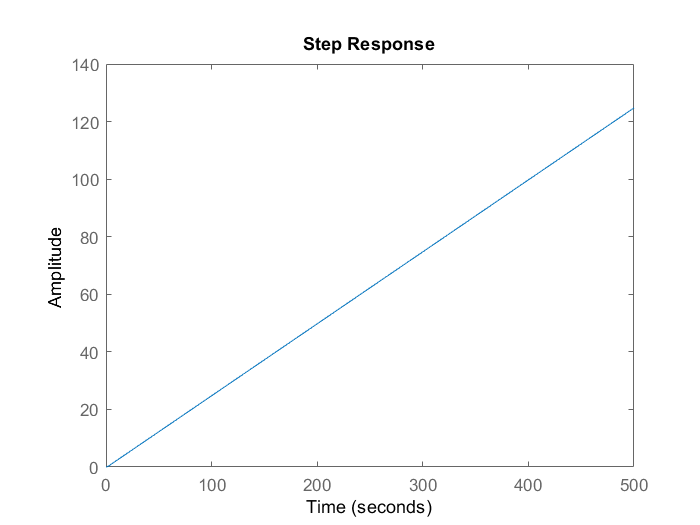

step(ft1)

stepinfo(ft1)

ans = struct with fields:
        RiseTime: NaN
    SettlingTime: NaN
     SettlingMin: NaN
     SettlingMax: NaN
       Overshoot: NaN
      Undershoot: NaN
            Peak: Inf
        PeakTime: Inf



%%%%%% sacar valores para segundo orden %%%%

%%%%%%%%%%%%%%%%%%%%%%%%   Control %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
syms s kp ki kd G(s) f(s) ki2 ki3 kd2 kd3
%GC depende tipo de controlador
%Gc=collect(expand(kp+ki/s+kd*s+kd2*s^2),s)%PIDD
Gc=collect(expand(kp+ki/s+ki2/(s^2)+kd*s+kd2*s^2),s) %PID

$$Gc = \frac{{\mathrm{kd}}_{2}\,s^{4}+\mathrm{kd}\,s^{3}+\mathrm{kp}\,s^{2}+\mathrm{ki}\,s+{\mathrm{ki}}_{2}}{s^{2}}$$

Ys=f(s)*G(s)/(1+f(s)*G(s))

$$Ys = \frac{G\left(s\right)\,f\left(s\right)}{G\left(s\right)\,f\left(s\right)+1}$$

%%%%%%%%%%%%%%%%%%Gc Retroalimentacion %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
F=collect(simplify(planta*Gc/(1+planta*Gc)),s);
F=eval(F);
[n, d] = numden(F);
d1=coeffs(d,s);
temp=d1(end);
d1=collect(d/temp);
n=n/temp;
F=n/d1; %funcion despejada
Ys=vpa(F,3)

$$Ys = \frac{0.5\,{\mathrm{kd}}_{2}\,s^{4}+0.5\,\mathrm{kd}\,s^{3}+0.5\,\mathrm{kp}\,s^{2}+0.5\,\mathrm{ki}\,s+0.5\,{\mathrm{ki}}_{2}}{s^{5}+\left(0.5\,{\mathrm{kd}}_{2}+2.0\right)\,s^{4}+\left(0.5\,\mathrm{kd}+2.0\right)\,s^{3}+0.5\,\mathrm{kp}\,s^{2}+0.5\,\mathrm{ki}\,s+0.5\,{\mathrm{ki}}_{2}}$$

d1=vpa(coeffs(d1,s),3)

$$d1 = \left(\begin{array}{cccccc} 0.5\,{\mathrm{ki}}_{2} & 0.5\,\mathrm{ki} & 0.5\,\mathrm{kp} & 0.5\,\mathrm{kd}+2.0 & 0.5\,{\mathrm{kd}}_{2}+2.0 & 1.0 \end{array}\right)$$

n1=coeffs(n,s);
%%%%%%%%%%%%%%%%%%%%%% Polinomio deseado canonico %%%%%%%%%%%%%%%%%%%%%%%
syms zeta wn s beta
gradopol=length(d1)-1

gradopol = 5


pd0=(s^2+2*zeta*wn*s+wn^2)*(s+beta*zeta*wn)^(gradopol-2)

$$pd0 = {\left(s+\beta \,\mathrm{wn}\,\zeta \right)}^{3}\,\left(s^{2}+2\,\zeta \,s\,\mathrm{wn}+{\mathrm{wn}}^{2}\right)$$

pdeseado=collect(pd0,s)

$$pdeseado = s^{5}+\left(2\,\mathrm{wn}\,\zeta +3\,\beta \,\mathrm{wn}\,\zeta \right)\,s^{4}+\left(3\,\beta^{2}\,{\mathrm{wn}}^{2}\,\zeta^{2}+6\,\beta \,{\mathrm{wn}}^{2}\,\zeta^{2}+{\mathrm{wn}}^{2}\right)\,s^{3}+\left(\beta^{3}\,{\mathrm{wn}}^{3}\,\zeta^{3}+6\,\beta^{2}\,{\mathrm{wn}}^{3}\,\zeta^{3}+3\,\beta \,{\mathrm{wn}}^{3}\,\zeta \right)\,s^{2}+\left(2\,\beta^{3}\,{\mathrm{wn}}^{4}\,\zeta^{4}+3\,\beta^{2}\,{\mathrm{wn}}^{4}\,\zeta^{2}\right)\,s+\beta^{3}\,{\mathrm{wn}}^{5}\,\zeta^{3}$$

d2s=coeffs(pdeseado,s);
%%%%%%%  ECUACIONES simbolicas %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%ecuaciones de acuerdo a incognitas y grado de polinomio deseado
eqns1 = d1==d2s;

ecuaciones1=vpa(eqns1.',5)

$$ecuaciones1 = \left(\begin{array}{c} 0.5\,{\mathrm{ki}}_{2}=\beta^{3}\,{\mathrm{wn}}^{5}\,\zeta^{3}\\ 0.5\,\mathrm{ki}=2.0\,\beta^{3}\,{\mathrm{wn}}^{4}\,\zeta^{4}+3.0\,\beta^{2}\,{\mathrm{wn}}^{4}\,\zeta^{2}\\ 0.5\,\mathrm{kp}=\beta^{3}\,{\mathrm{wn}}^{3}\,\zeta^{3}+6.0\,\beta^{2}\,{\mathrm{wn}}^{3}\,\zeta^{3}+3.0\,\beta \,{\mathrm{wn}}^{3}\,\zeta \\ 0.5\,\mathrm{kd}+2.0=3.0\,\beta^{2}\,{\mathrm{wn}}^{2}\,\zeta^{2}+6.0\,\beta \,{\mathrm{wn}}^{2}\,\zeta^{2}+{\mathrm{wn}}^{2}\\ 0.5\,{\mathrm{kd}}_{2}+2.0=2.0\,\mathrm{wn}\,\zeta +3.0\,\beta \,\mathrm{wn}\,\zeta \\ 1.0=1.0 \end{array}\right)$$

%%%%%%%%%%%%%%%%%%%%%%% valores pd deseados %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ts=15

ts = 15

%ts=0.95*tsteorico
zeta=0.95

zeta = 0.9500

beta=10 %dejar expresado o comentar linea si se quiere despejar

beta = 10

wn=4/(ts*zeta)

wn = 0.2807

Mp=exp(-(zeta/(sqrt(1-zeta^2)))*pi)*100 %

Mp = 0.0071

%%%%%%%%%  ECUACIONES EVALUANDO zeta wm %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%ecuaciones de acuerdo a incognitas y grado de polinomio deseado
eqns = eval(d1)==eval(d2s);

ecuacionesfull=vpa(eqns.',5)

$$ecuacionesfull = \left(\begin{array}{c} 0.5\,{\mathrm{ki}}_{2}=1.4942\\ 0.5\,\mathrm{ki}=11.795\\ 0.5\,\mathrm{kp}=30.971\\ 0.5\,\mathrm{kd}+2.0=25.679\\ 0.5\,{\mathrm{kd}}_{2}+2.0=8.5333\\ 1.0=1.0 \end{array}\right)$$

%%%%%%%%%%%%%%%%%% solve equations %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%ki ki2 ki3 kp kd kd2 kd3 beta
incognitas=[ki ki2 kp kd kd2] %PID

$$incognitas = \left(\begin{array}{ccccc} \mathrm{ki} & {\mathrm{ki}}_{2} & \mathrm{kp} & \mathrm{kd} & {\mathrm{kd}}_{2} \end{array}\right)$$

S = solve(eqns,incognitas);%se agregan incognitas o beta en caso tal
ki=eval(S.ki)

ki = 23.5890

ki2=eval(S.ki2)

ki2 = 2.9883

kp=eval(S.kp)

kp = 61.9422

kd=eval(S.kd)

kd = 47.3576

kd2=eval(S.kd2)

kd2 = 13.0667

%beta=eval(S.beta)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SACAR FT y GRAFICAR %%%%%%%%%%%%%
Gc

$$Gc = \frac{{\mathrm{kd}}_{2}\,s^{4}+\mathrm{kd}\,s^{3}+\mathrm{kp}\,s^{2}+\mathrm{ki}\,s+{\mathrm{ki}}_{2}}{s^{2}}$$

Gcevaluada=vpa(eval(Gc),3)

$$Gcevaluada = \frac{13.1\,s^{4}+47.4\,s^{3}+61.9\,s^{2}+23.6\,s+2.99}{s^{2}}$$

planta

$$planta = \frac{0.5}{s^{3}+2.0\,s^{2}+2.0\,s}$$

%%%%%%%DESPEJE FUNCION FINAL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Ff=collect(simplify(eval(F)));
[n, d] = numden(Ff);
d1=coeffs(d,s);
n1=coeffs(n,s);
temp=d1(end);
d=collect(d/temp);
n=n/temp;
F=n/d; %funcion despejada
Funcionfinal=vpa(F,3)

$$Funcionfinal = \frac{6.53\,s^{4}+23.7\,s^{3}+31.0\,s^{2}+11.8\,s+1.49}{s^{5}+8.53\,s^{4}+25.7\,s^{3}+31.0\,s^{2}+11.8\,s+1.49}$$

%%%%%%%%% GRAFICAR %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
n1=double(n1/temp);
d1=double(d1/temp);
ft2=tf(fliplr(n1),fliplr(d1))


ft2 =
 
     6.533 s^4 + 23.68 s^3 + 30.97 s^2 + 11.79 s + 1.494
  ---------------------------------------------------------
  s^5 + 8.533 s^4 + 25.68 s^3 + 30.97 s^2 + 11.79 s + 1.494
 
Continuous-time transfer function.



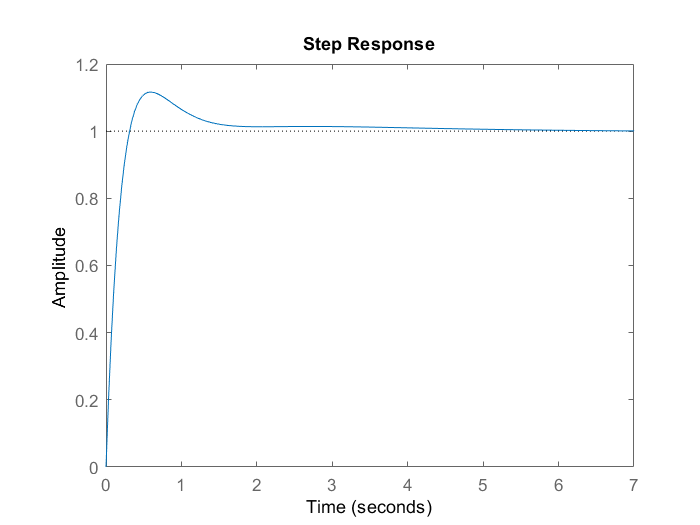

step(ft2)

info2=stepinfo(ft2)

info2 = struct with fields:
        RiseTime: 0.2250
    SettlingTime: 1.5189
     SettlingMin: 0.9003
     SettlingMax: 1.1165
       Overshoot: 11.6495
      Undershoot: 0
            Peak: 1.1165
        PeakTime: 0.5872


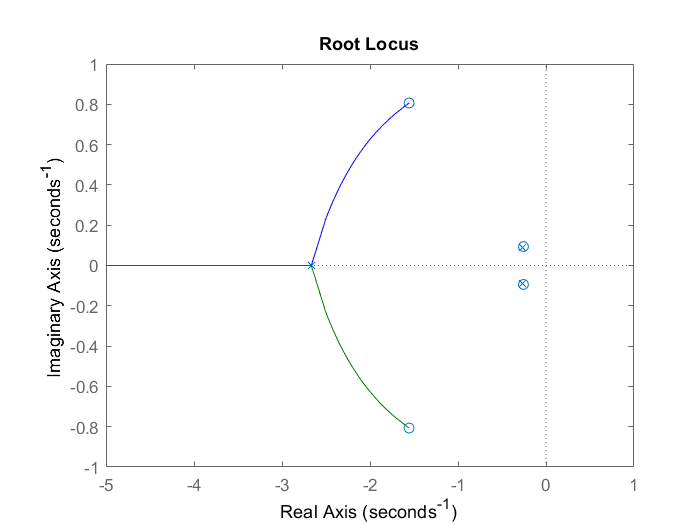

rlocus(ft2)

polos2=vpa(roots(fliplr(d1)),3)

$$polos2 = \left(\begin{array}{c} -2.67+3.05\,10^{-5}\,\mathrm{i}\\ -2.67-3.05\,10^{-5}\,\mathrm{i}\\ -2.67\\ -0.267+0.0876\,\mathrm{i}\\ -0.267-0.0876\,\mathrm{i} \end{array}\right)$$